# Homework 3

## Due Friday, March 5 before 5:00pm

*For Part 1, submit your handwritten work using Gradescope. For Parts 2-4, use [Live Editor > Save > Export to PDF] to prepare your submission for Gradescope.*

## Part 1: Deriving an estimator for $y=\beta_1 x$

In class we derive least-squares estimators for the linear models $y=\beta_0$ and $y=\beta_0+\beta_1x$. For this exercise you will derive a formula to fit a single parameter model $y=\beta_1x$ to a set of $n$ datapoints.

**a.)** Begin with the total quadratic loss $\sum_{i=1}^n(y^\mathrm{pred} - y^\mathrm{true})^2$. Write this expression after substituting the linear model for $y^\mathrm{pred}$.

**b.)** Our goal is to minimize the total loss, which can be found when the partial derivative of the loss with respect to the parameter $\beta_1$ is zero. Find and expression for $\beta_1$.

**c.)** Using your formula for $\beta_1$, fit the model $y=\beta_1x$ to the five data points in the table on page 58 of the textbook. Compare your value of $\beta_1$ to the value found when fitting the data to the model $y=\beta_0+\beta_1x$ in section 8.3.2.

**d.)** We want to be sure that we're minimizing, not maximizing the sum squared error. Using a second derivative test, show that your estimate for $\beta_1$ is a minimum. Be sure to explain your reasoning.

**Parts 2-4 use data from the MAT file HW3_data**`.mat`**. **Download this file and run

load HW3_data.mat

to load variables `x`, `y`, `blood`, and `ecm` into the workspace.

## Part 2: Polynomial Fitting

Variables `x` and `y` contain 12 values from an unknown cubic polynomial, i.e.


$$y = \beta_0+\beta_1x+\beta_2x^2+\beta_3x^3$$


Using the values `x` and `y`, compute estimates for parameters $\beta_0, \ldots, \beta_3$ using linear regression. **For this problem, you are not allowed to use **`fitlm`**, **`regress`**, **`polyfit`**, or any other linear regression or curve fitting tools.** You must construct the design matrix and calculate parameter estimates via pseudoinversion.

% place your code here

Using your parameter estimates, plot the points in variables `x` and `y` and a line corresponding to the best fit polynomial. Both the points and the line should be on the same plot.

% place your code here

## Part 3: Cell Growth

Variables `t` and `cells` contain six cell counts for dividing mammalian cells in a culture dish. (The times in `t` are in hours.) Your task is to find the exponential growth rate of the cells using linear regression. **For this problem, you are not allowed to use **`fitlm`**, **`regress`**, **`polyfit`**, or any other linear regression or curve fitting tools.**

**a.)** Plot the number of cells over time.

% place your code here

**b.)** Set up a design matrix for the linearized exponential growth equation from section 9.4.

% place your code here

**c.)** Calculate the pseudoinverse of the design matrix and use it to fit your model. 

% place your code here

**d.)** Calculate the exponential growth rate of the cells. What are the units?

*<place your answer here>*

**e.)** Use the fitted parameters to find the inital number of cells. How does this value compare with the number of cells at t = 0 h in your data?

*<place your answer here>*

## Part 4: Blood Metabolite Diagnostic for Fungal Infections 

You are tasked with diagnosing a bloodborne fungal infection. Ideally, you would measure the number of colony forming units (CFUs) per ml of blood. However, the fungus is slow growing outside the body, so accurate CFU counts take weeks. Instead, you hope to use standard measurements from a blood metabolic panel to predict the CFUs/ml in a sample.

The Matlab table blood contains data from a 250-patient clinical trial. Each datapoint has values for all 14 standard blood metabolite readings:

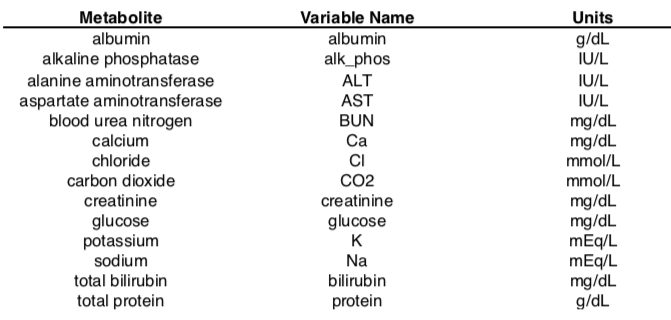

The blood table also contains the log(CFU) counts for each sample. (*Note that we use log(CFU) since CFU counts vary exponentially. This is unrelated to the logit function or logistic regression.*)

**a.)** Using linear regression, build a model that predicts log(CFU) counts with blood metabolite readings. 

% place your code here

Which metabolite readings are significantly predictive of the CFU counts? Do these metabolite levels increase or decrease as the fungus count increases?

*<place your answer here>*

**b.)** During sepsis, the number of fungal cells in the blood increases by 100 fold. Would your model be able to predict this level of change using metabolites? Why or why not?

*<place your answer here>*